# Copyright of this code belongs to Frank Lawless (flawless@uncc.edu).

Do not distribute this code.

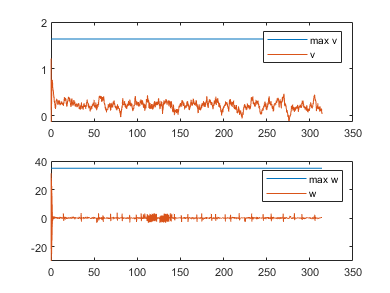

clear all 
close all

% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k m d;
D = .0469; k = .5;
h = .1; 

non_linear_control = false; m = .2; % Control II & switch threshold
d = 0; % delay amount \delta
speed =  .01;

% noise magnitudes
angular_noise = .5;
linear_noise = .5;

%road trajectory and map
position = importdata("new_road.csv")';
map = importdata("road_map_without_lines.mat")/1000*40;
down_sample_amount = 50; 

statea(:,1) =[position(1,1)-D-2; position(2,1)+2; 0];

state(:,1) =[position(1,1)-D-2; position(2,1)+2; 0];

xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1);  
theta_hat(1) = state(3,1);

xba(1) = state(1,1) + D*cos(state(3,1));
yba(1) = state(2,1) + D*sin(state(3,1));
thetaa(1) = state(3,1); 

T = size(position,2)-1;
t = 1:T;
xVelocity = (position(1,t+1) - position(1,t))/h;
yVelocity = (position(2,t+1) - position(2,t))/h;
for t = 1 : T
    n1(t) = linear_noise*randn(1);
    n2(t) = angular_noise*randn(1);

    % x= current state
    xa = [xba(t); yba(t); thetaa(t)];
    x = [xb(t); yb(t); theta_hat(t); theta(t)];
    
    % controller returns the desired velocities
    [va, wa] = controller(xa, xVelocity(t), yVelocity(t),position(:,t),non_linear_control);
    [v(t), w(t)] = controller(x(1:3,1), xVelocity(t), yVelocity(t),position(:,t),non_linear_control);
    % use the dynamics with desired velocities to generate the velocities
    dot_xa = dynamics(xa,va,wa,n1(t),n2(t));
    dot_x(:,t) = dynamics([x(1); x(2); x(4)],v(t),w(t),n1(t),n2(t));
    
     linear_vela(t) = va+n1(t);
     angular_vela(t) = wa+n2(t);
     
     linear_vel(t) = v(t)+n1(t);
     angular_vel(t) = w(t)+n2(t);
     
    % centroid dynamics
    %actual
    statea(:,t+1) = statea(:,t) + h* [(va+n1(t))*cos(statea(3,t)); (va+n1(t))*sin(statea(3,t)); wa+n2(t)];  
    %noise
    state(:,t+1) = state(:,t) + h* [(v(t)+n1(t))*cos(state(3,t)); (v(t)+n1(t))*sin(state(3,t)); w(t)+n2(t)];
    
    % integrate the position to get the new position
    
    %actual
    xba(t+1) = xba(t) + dot_xa(1)*h;
    yba(t+1) = yba(t) + dot_xa(2)*h;
    thetaa(t+1) = thetaa(t) + dot_xa(3)*h;
    
    %estimated
    xb(t+1) = xb(t) + dot_x(1,t)*h;
    yb(t+1) = yb(t) + dot_x(2,t)*h;
    theta(t+1) = theta(t) + dot_x(3,t)*h;
    
    theta_hat = estimated_theta(t,n1,state,theta,v,w);
end
 
% error norm

for i = 1:length(position)
    error = [position(1,i) - xb(i); position(2,i) - yb(i)];
    error_norm(i) = norm(error);
    Q(i) = k*2*cos(thetaa(i)-theta(i));
    theta_e(i) = thetaa(i)-theta(i);
end

% velocity norm
velocity_norm(1) = 0;
for i = 1:length(xb)-1
Z = [xVelocity(i); yVelocity(i)];
reference_velocity_norm(i) = norm(Z);
end

% velocity bounds
for i = 1:length(xb)-1
max_v(i) = max(reference_velocity_norm)+k*max(error_norm);
max_w(i) = 1/D*max(reference_velocity_norm)+k/D*max(error_norm);
end

% upper bound of e
 a = (min(Q(t)-min(Q(t))*.99))^(1/2)*.65;

 c1 = k*2*cos(max(theta_e))-a^2;
 c2 = (1/a^2)*max(1/2-.5*cos(2*theta_e))*max(reference_velocity_norm)^2;
for t = 0:(length(xb))-1
    e_upper(t+1) = exp(-c1/2*t*h)*error_norm(1)+sqrt(c2/c1)*sqrt(1-exp(-c1*t*h));
end

%bounded velocities
figure
subplot(2,1,1)
plot([1:length(xb(1,:))-1]*h, max_v)
hold on
plot([1:length(xb(1,:))-1]*h, v)
legend('max v','v','location','best')
hold off
subplot(2,1,2)
plot([1:length(xb(1,:))-1]*h, max_w)
hold on
plot([1:length(xb(1,:))-1]*h, w)
legend('max w','w','location','best')
hold off

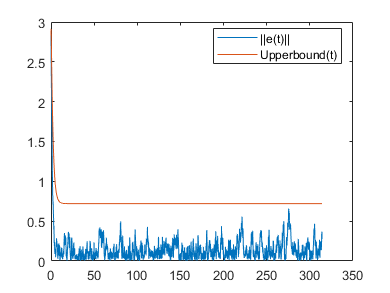


% bounded error
figure
plot([0:length(xb(1,:))-1]*h, error_norm)
hold on
plot([0:length(xb(1,:))-1]*h, e_upper)
legend('||e(t)||','Upperbound(t)','location','best')
hold off

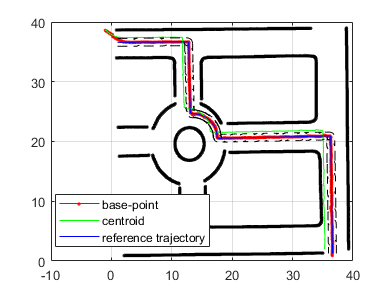


figure
plot(map(1,:), map(2,:)+20/1000,'.','color','k')
hold on;
plot(xb, yb, '.-','color','r')
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:),'color','b');
plot_tolerance(position,max(error_norm(50:end)));
grid on;
legend('','base-point', 'centroid', 'reference trajectory',"", "location", 'best')
hold off

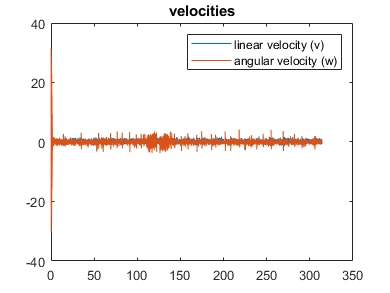

 
figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('linear velocity (v)', 'angular velocity (w)')
title("velocities")

function [v, w] = controller(x, xVelocity, yVelocity,position,non_linear_control)
global D k m

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

if norm(E) > m && non_linear_control == 1
        v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
    else
    v_feedback = [xVelocity; yVelocity] - k*E;
end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end

function theta_hat = estimated_theta(t,n1,state,theta,v,w)
global h d
    if t-d >= 1
        i=0;
    for l = t-d:t
        i = i+1;
        w_delay(i) = w(l);
    end
         theta_hat(t+1) = atan2((state(2,t+1-d)-state(2,t-d))/(v(t-d)+n1(t-d)), ...
             (state(1,t+1-d)-state(1,t-d))/(v(t-d)+n1(t-d))) + sum(w_delay)*h;
    else
        i=0;
        for l = 1:t
        i = i+1;
        w_delay(i) = w(l);
        end
        theta_hat(t+1) = theta(1)+pi+ sum(w_delay)*h;
    end
end

function new_points = interpolate(position,max_speed)   
    global h 
    x1 = position(1,1); x2 = position(1,2);
    y1 = position(2,1); y2 = position(2,2);
    distance = norm([x2; y2]-[x1; y1]);
    
    step_size = distance/(max_speed*h);
    interval0 = linspace(0,distance,step_size);
    interval1 = interval0(1:length(interval0)-1);
    
    x_out= []; y_out = [];
    if length(interval1) > 1
    for a = 2:length(interval1)
        i = interval1(a);
        x_n = x1 + (i/distance)*(x2 - x1);
        y_n = y1 + (i/distance)*(y2 - y1);
        x_out = [x_out x_n];
        y_out = [y_out y_n];
    end
    else
        x_out = []; y_out = [];
    end
    new_points = [position [x_out; y_out]];
end

function position_old = abstraction(position_old,threshold)
global h
ptr_1 = 1;
ptr_2 = 2;
index = [];
while ptr_2 < length(position_old)
    while norm([position_old(:,ptr_2)-position_old(:,ptr_1)]) < threshold*h
        index = [index ptr_2];
        ptr_2 = ptr_2 + 1;
        if ptr_2 > (length(position_old))
            break
        end
    end
    ptr_1 = ptr_2;
    ptr_2 = ptr_2+1;
   
    if ptr_2 == length(position_old)
        if norm([position_old(:,ptr_2) - position_old(:,ptr_1)]) < threshold*h
            index = [index ptr_2];
        end
    end
end

position_old(:,index) = [];
end

function [tolerance1, tolerance2] = plot_tolerance(z,d) % function to plot tolerance
% initialize distances between edges of the tolerance line
s = [d; -d];   
for i = [1:length(z)-1]
  theta = atan2(z(2,i+1)-z(2,i),(z(1,i+1)-z(1,i)));
% calcualte 1x2 array with edge points
    x(:,i) = s*sin(theta) + z(1,i);
    y(:,i) = -s*cos(theta) + z(2,i);
  
    
end
tolerance1(1,:) = x(1,:);
tolerance1(2,:) = y(1,:);
tolerance2(1,:) = x(2,:);
tolerance2(2,:) = y(2,:);
plot(x(1,:),y(1,:),'--','color','k')
plot(x(2,:),y(2,:),'--','color','k')
end